# Lab 5 report by Mikołaj Suchoń

## Ex.1.1

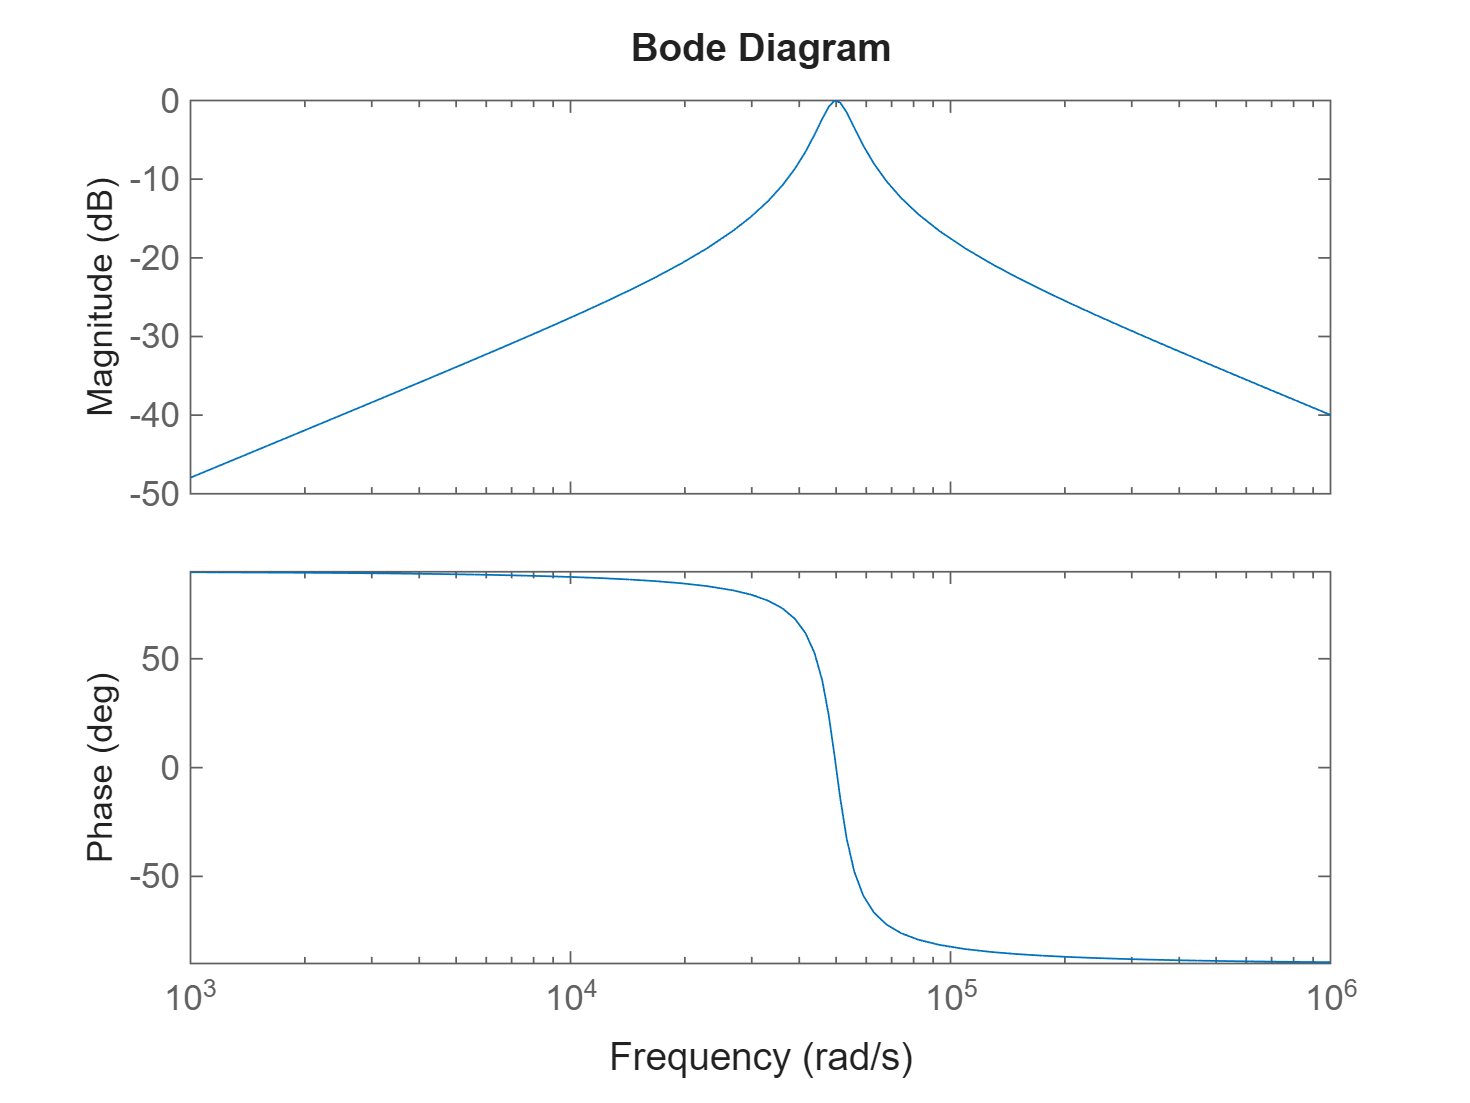

clear
R=10;
C=1*10e-6;
L=4*10e-6;
num=[L,0];
den=[L*C*R,L,R];
den2=[L*C*R/2,L,R/2]; %R=5
den3=[L*C*R*10,L,R*10]; %R=100
sys=tf(num,den);
bode(sys)

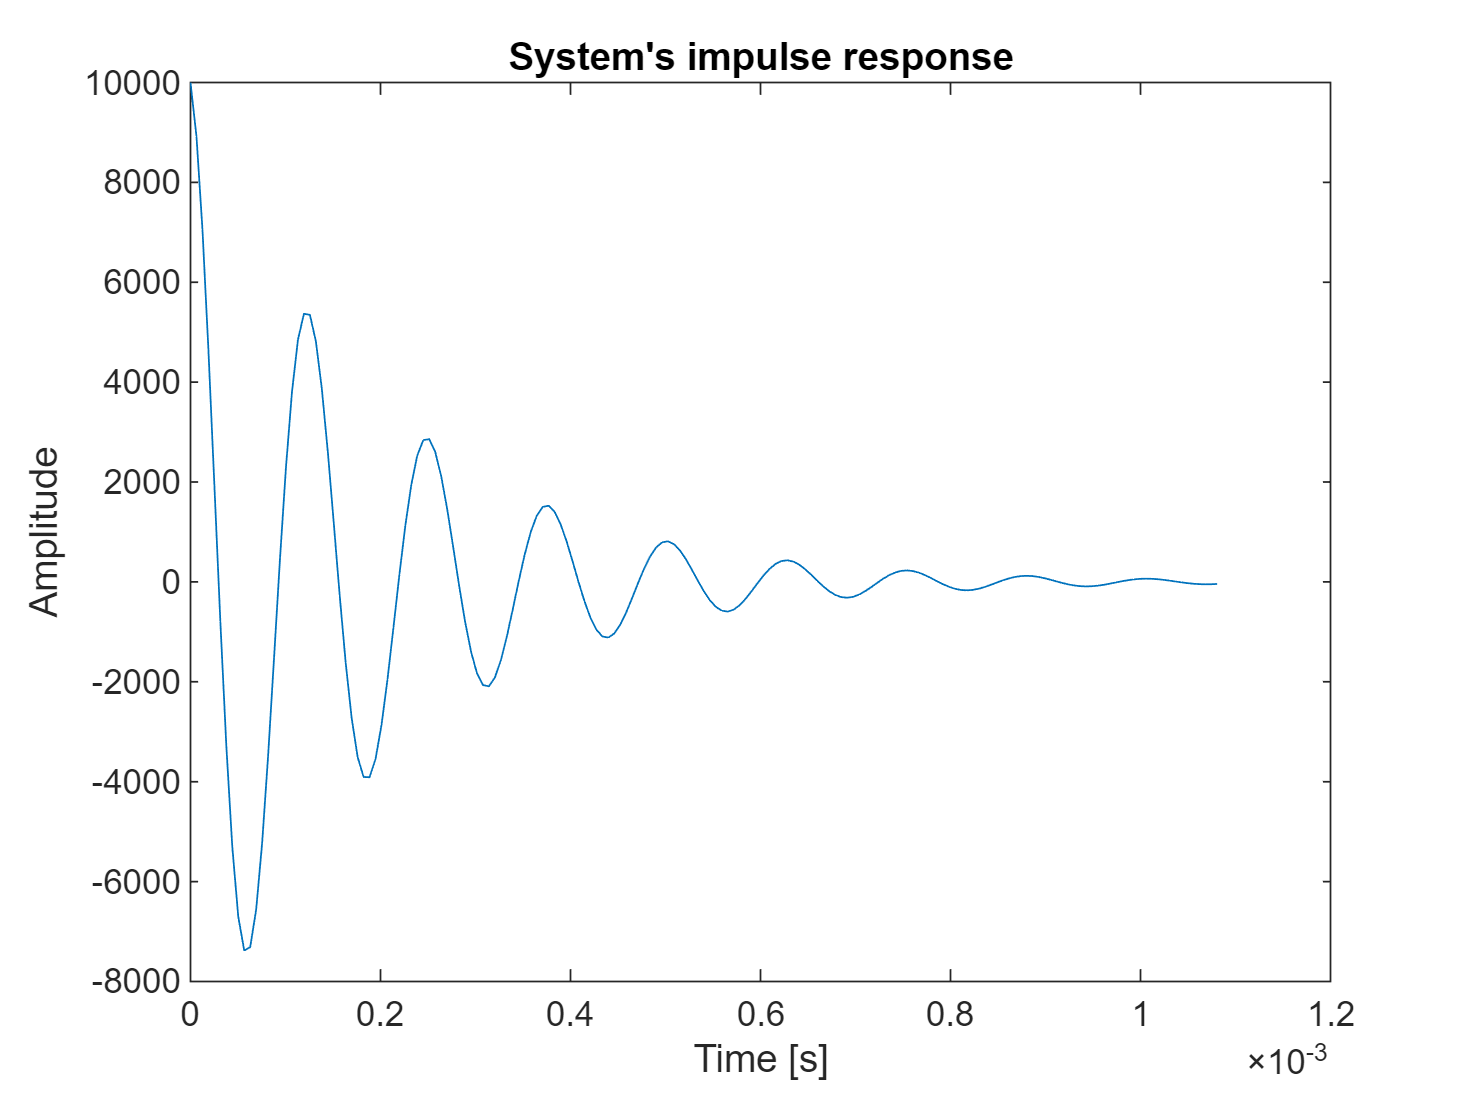


[y,tOut] = impulse(sys);
plot(tOut,y)
title("System's impulse response")
xlabel('Time [s]')
ylabel('Amplitude')

Resonant angular frequency:

w0=1/sqrt(L*C)

w0 = 5.0000e+04

fs=2*10^6/2*pi

fs = 3.1416e+06

The calculated angular frequency is consistent with bode plot

To **capture the full bandwidth of a system** as shown in a **Bode plot**, the **sampling frequency** must satisfy the **Nyquist criterion**, which states: fs≥2⋅fmax

Where:

- fmax is the **maximum frequency of interest** (i.e. the highest frequency shown or relevant in the Bode plot),

- fs is the **sampling frequency**.

In practice it is recommended to use a sampling rate 2-5 x higer than fmax

## Ex.1.2

dt=1/fs;
% out=sim("Lab5sim"); %simulink model
% save out out %saving results to not need to run the simulation every time
load out 
x1=out.x1.Data;
y1=out.y1.Data;

## Ex.1.3

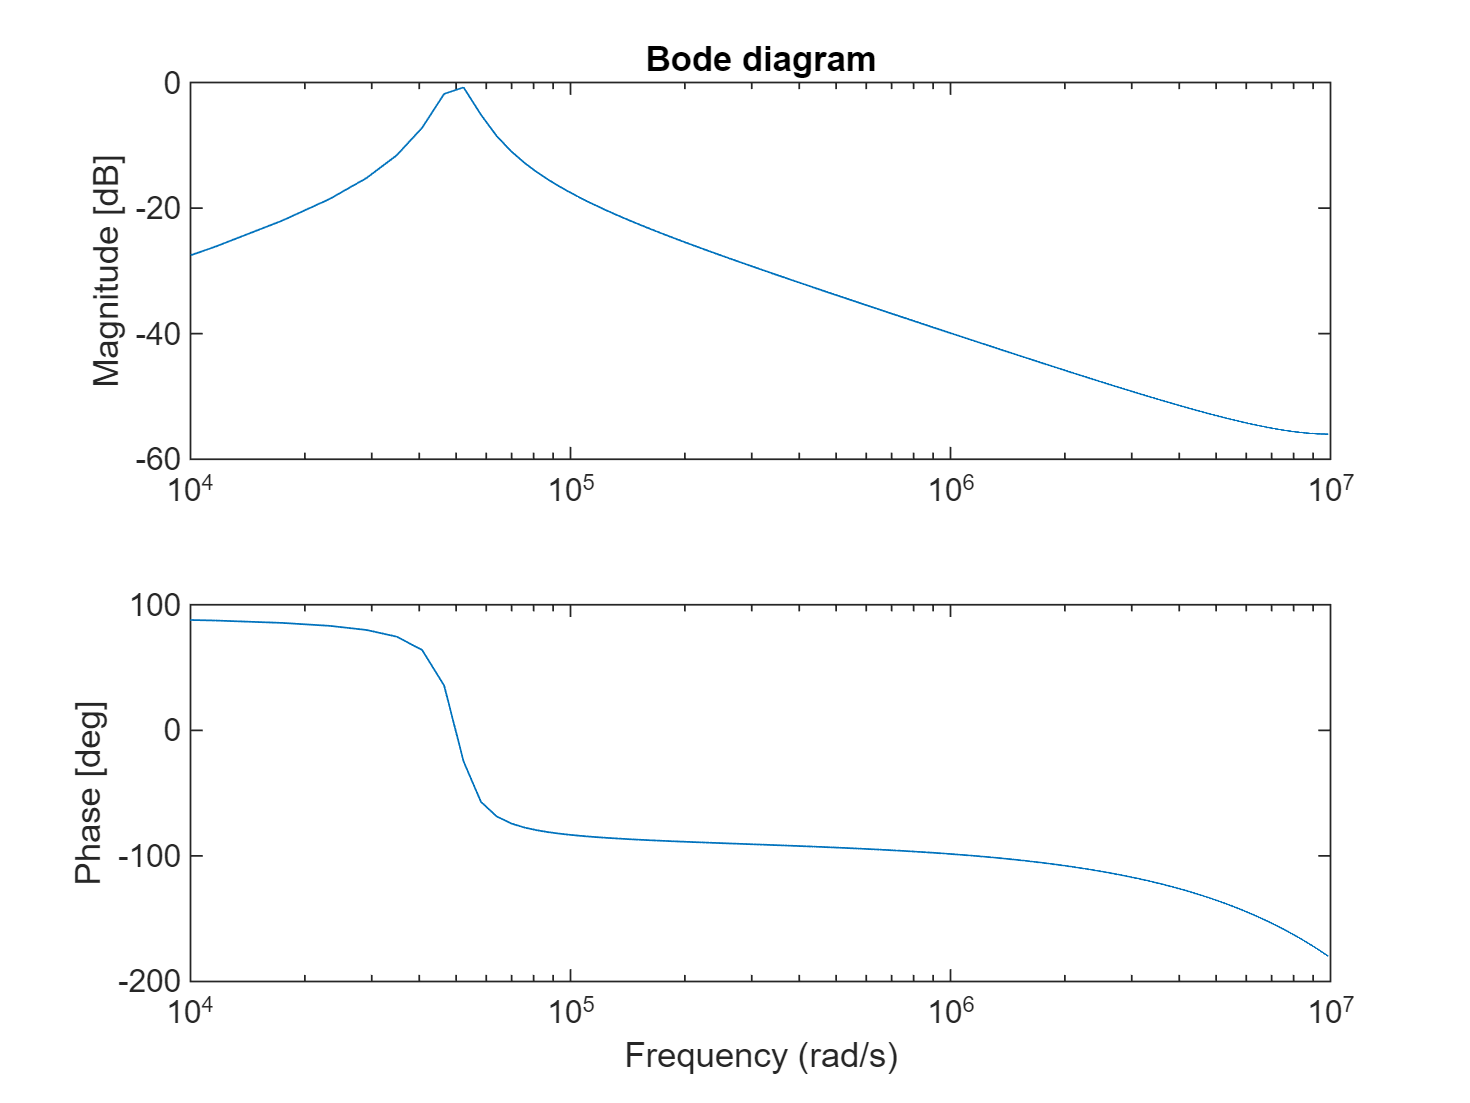

ownBode(x1,y1,fs)

This bode plot, resulting from own method, is identical to the bode obtained via matlab function. Given the difference in sampling frequency, the scope of frequencies shown is different.

### Ex.1.4.

Damping factor calculation using the logarithmic method:

x1=2840;
x0=5369;
eps1=log(x0/x1)/(2*pi)  

eps1 = 0.1014

Half power method:

w1=45000;
w2=55000;
wr=51000;
eps2=(w2-w1)/(2*wr)

eps2 = 0.0980

Resuslts using the logarythmic method do not differ from the results obtained from the half power method by more then the mesurement error allows for.

## Ex.1.5

x2=out.x2.Data;
y2=out.y2.Data;
x3=out.x3.Data;
y3=out.y3.Data;


### For R=5 [ohm]:

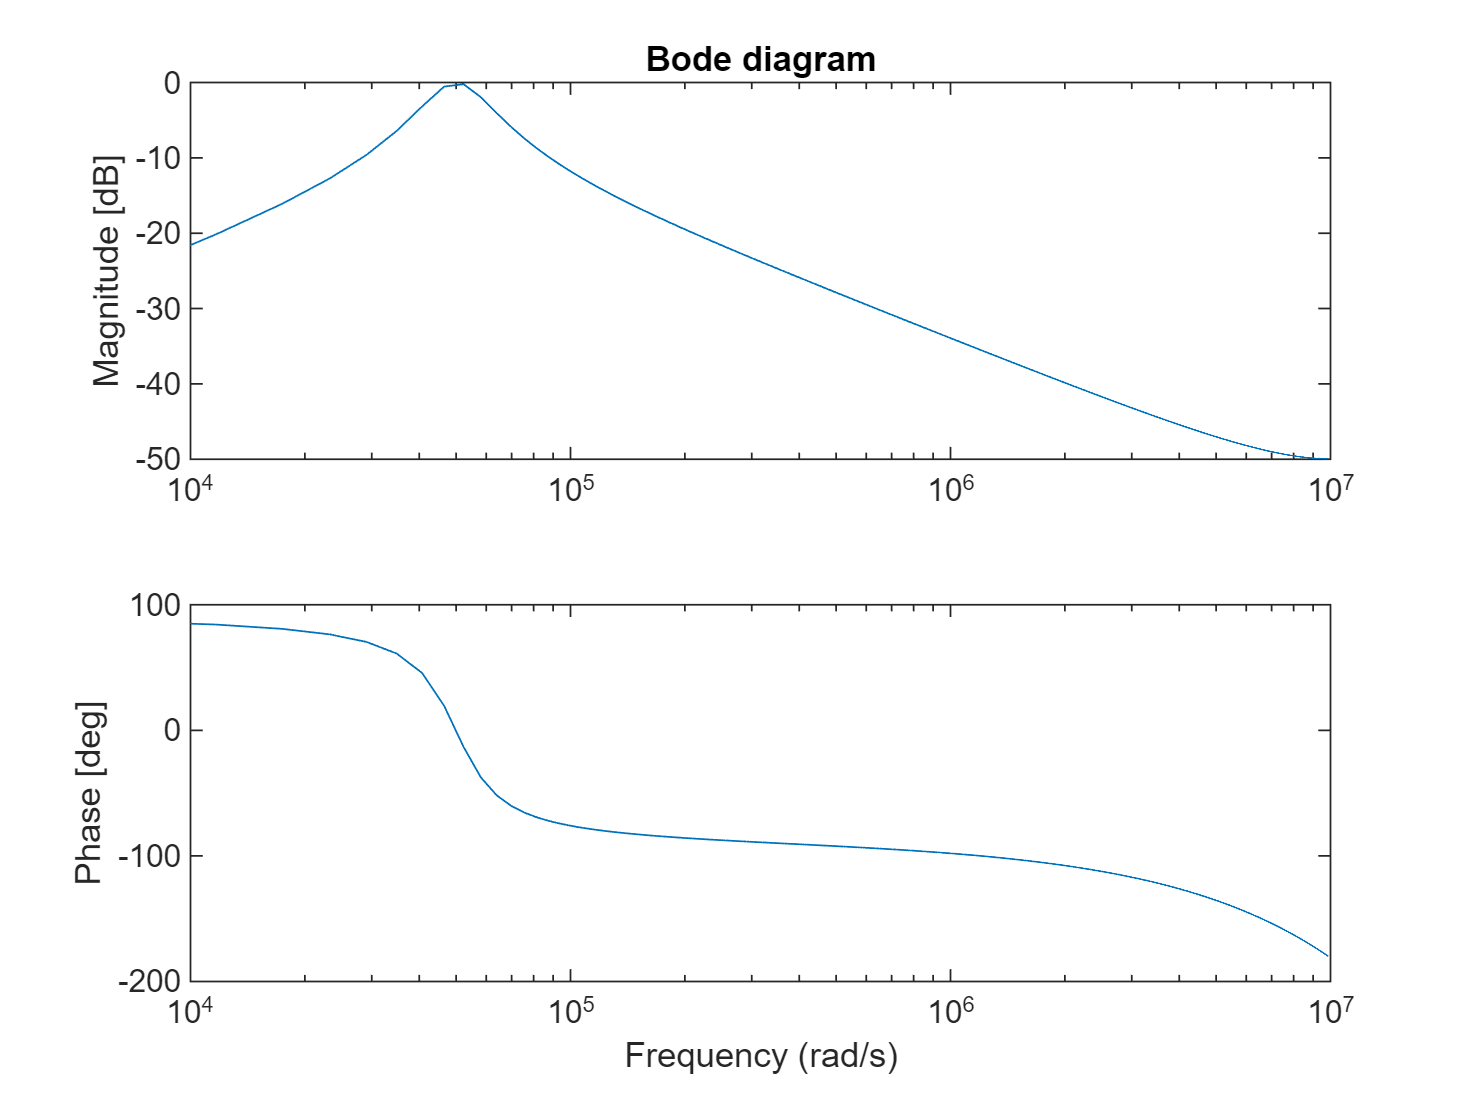

ownBode(x2,y2,fs)

### For R=100 [ohm]:

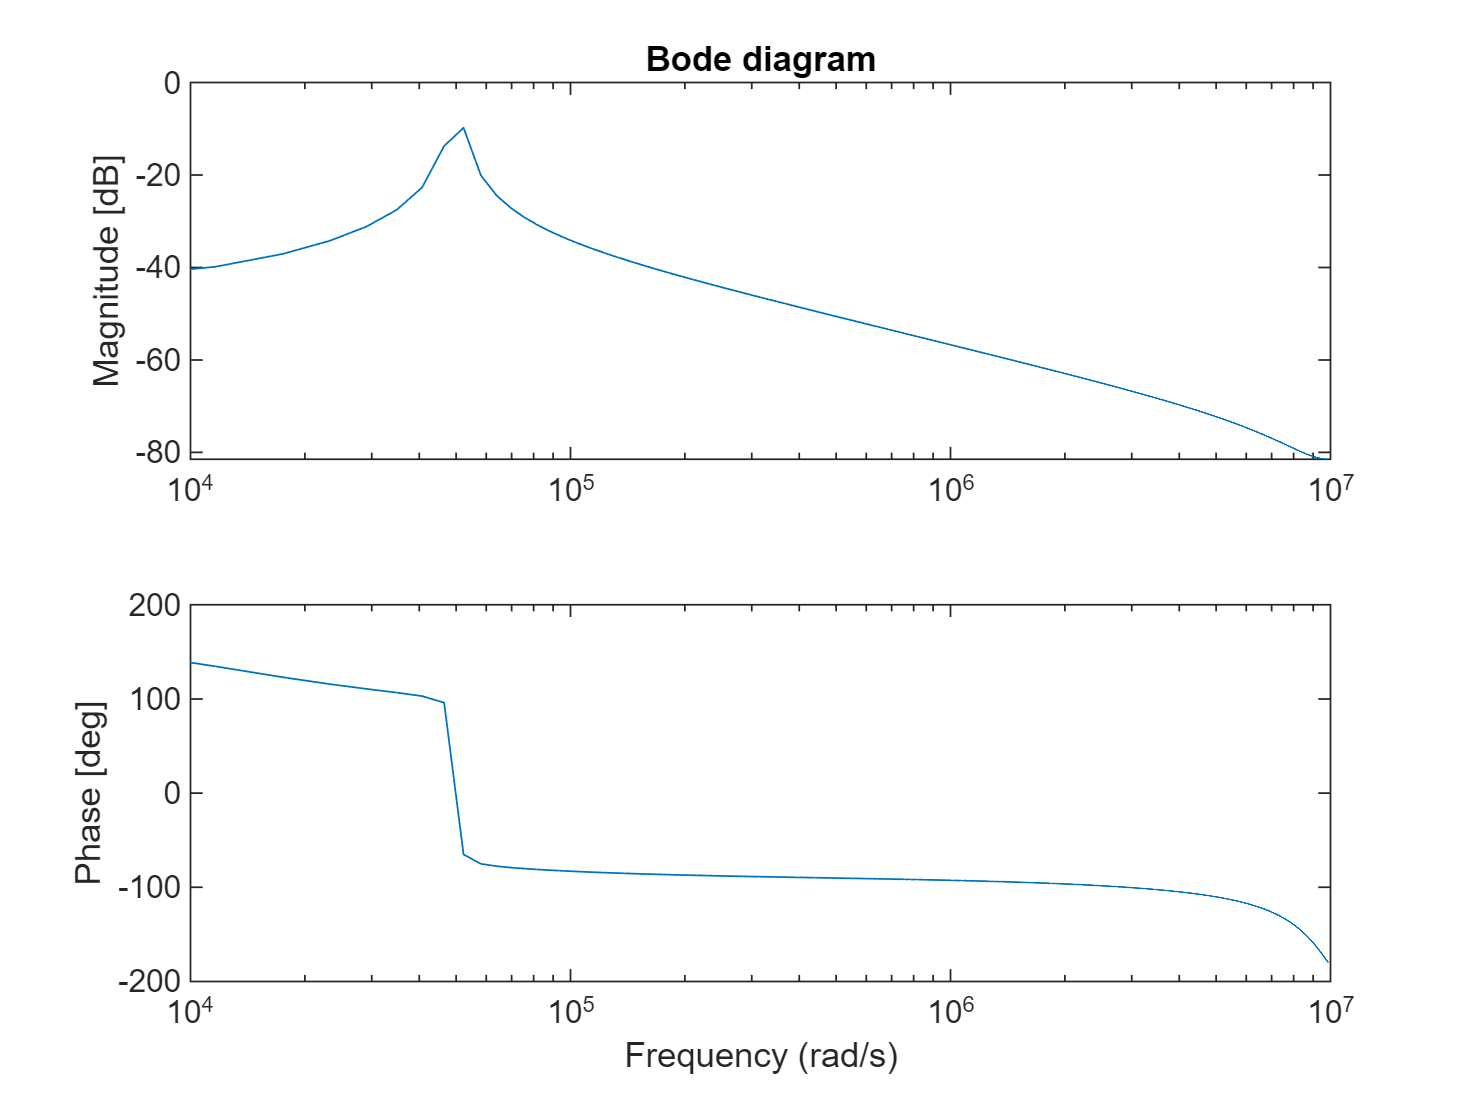

ownBode(x3,y3,fs)

### Ex.2.1

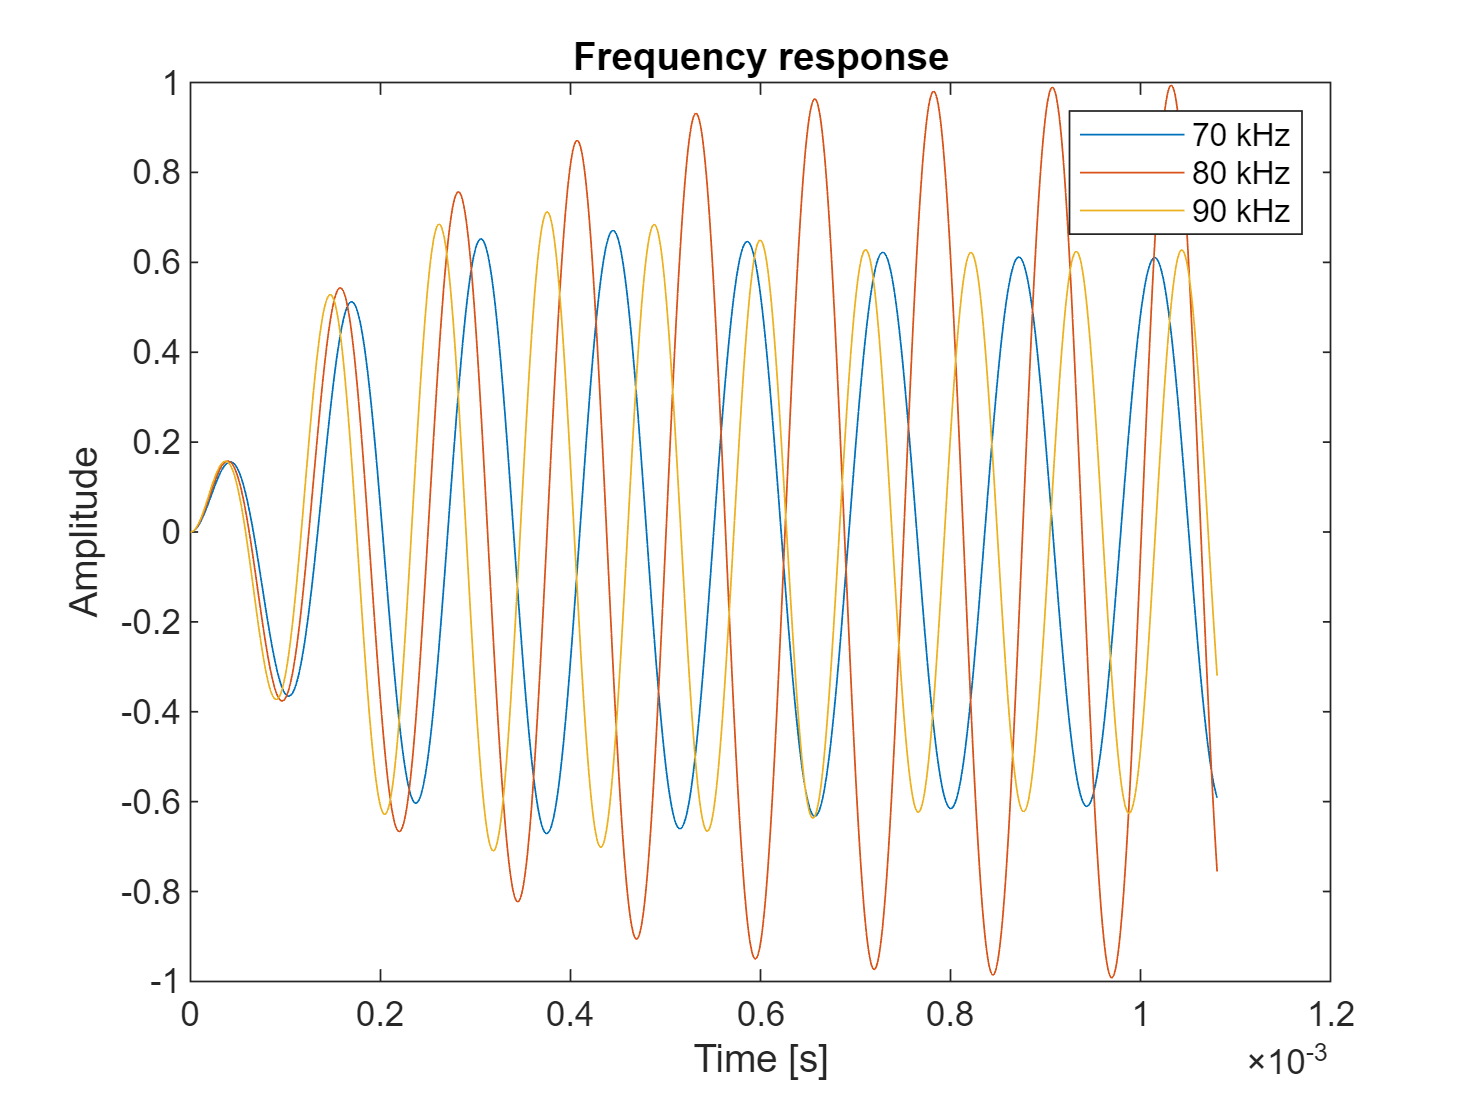

x4=out.x4.Data;
y4=out.y4.Data;
x5=out.x5.Data;
y5=out.y5.Data;
x6=out.x6.Data;
y6=out.y6.Data;
t=out.x1.Time;
figure
plot(t,y4);hold on;
plot(t,y5)
plot(t,y6);hold off;
title('Frequency response')
xlabel('Time [s]')
ylabel('Amplitude')
legend('70 kHz','80 kHz','90 kHz')

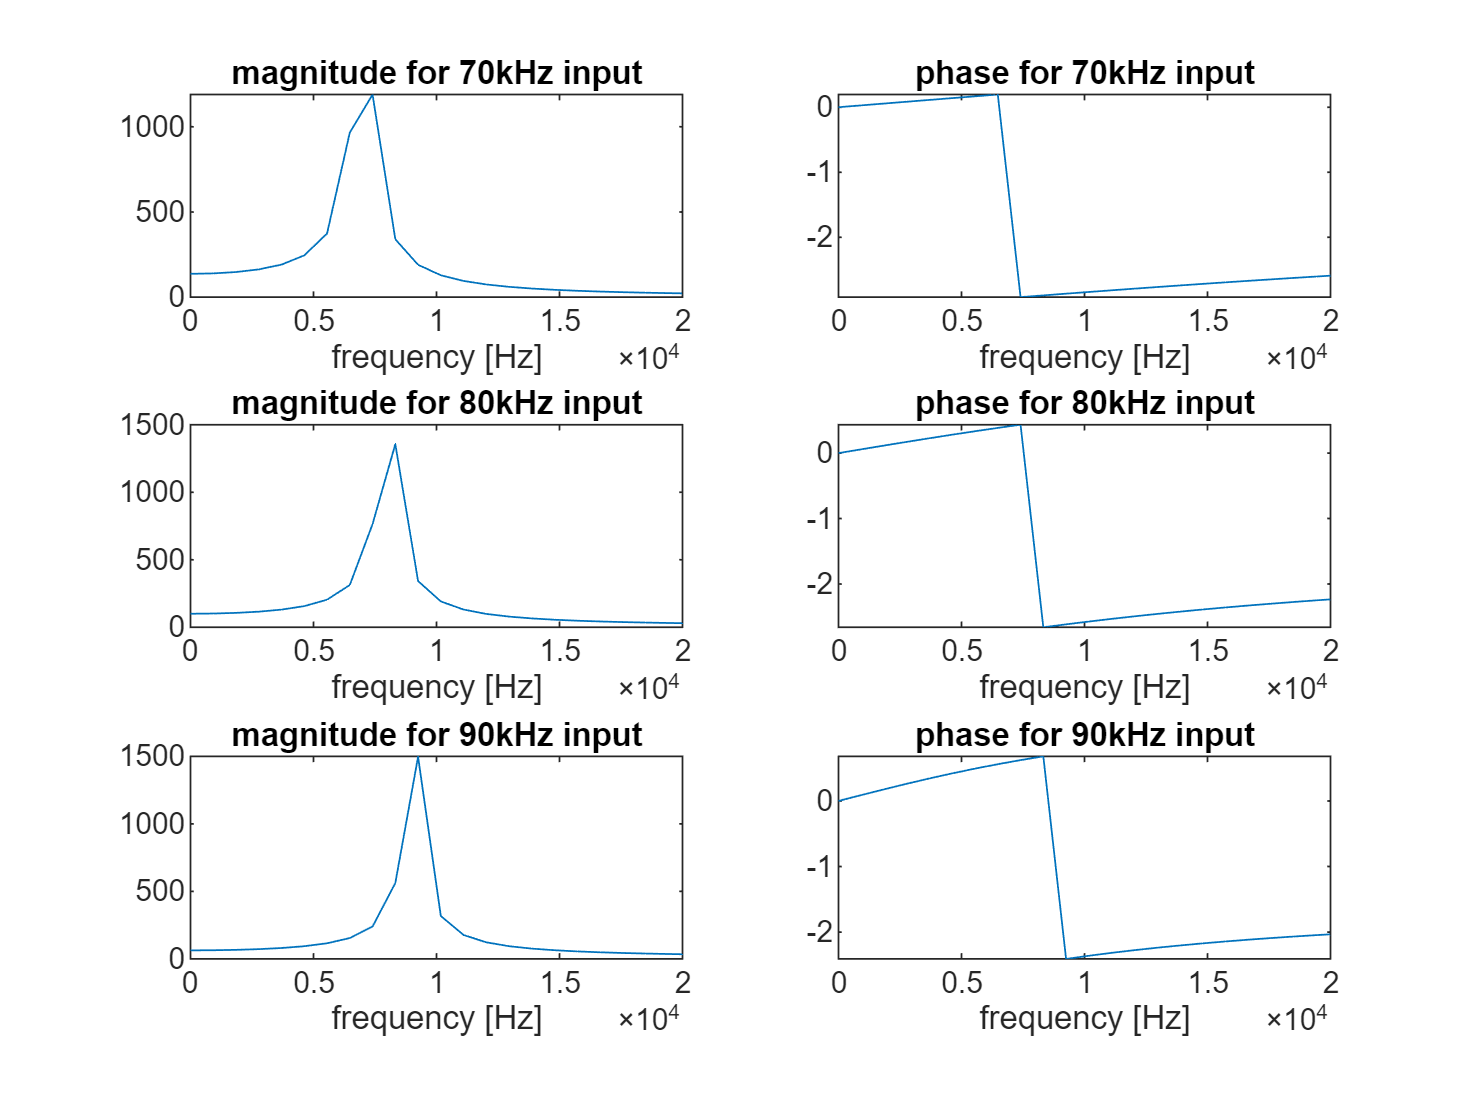


N=length(x4);
df=fs/N;
f=(0:df:fs-1);
figure
subplot(321)
plot(f,abs(fft(x4)))
title('magnitude for 70kHz input')
xlabel('frequency [Hz]')
xlim([0,2e4])
subplot(322)
plot(f,angle(fft(x4)))
title('phase for 70kHz input')
xlabel('frequency [Hz]')
xlim([0,2e4])
subplot(323)
plot(f,abs(fft(x5)))
title('magnitude for 80kHz input')
xlabel('frequency [Hz]')
xlim([0,2e4])
subplot(324)
plot(f,angle(fft(x5)))
title('phase for 80kHz input')
xlabel('frequency [Hz]')
xlim([0,2e4])
subplot(325)
plot(f,abs(fft(x6)))
title('magnitude for 90kHz input')
xlabel('frequency [Hz]')
xlim([0,2e4])
subplot(326)
plot(f,angle(fft(x6)))
title('phase for 90kHz input')
xlabel('frequency [Hz]')
xlim([0,2e4])

for input 70kHz: frequency f1 = 74000Hz, phase for f1 --> w1=-2.91 rad

for input 80kHz: frequency f2 = 83000Hz, phase for f2 --> w2=-2.66 rad

for input 90kHz: frequency f3 = 92000Hz, phase for f3 --> w2=-2.41 rad

Conclusion: 

The time plot of the signal for 80kHz input has the highest amplitude, signals of input frequency 70kHz  and 80kHz have a lower amplitude. This is consisten with the bode plot because at 80kHz the attenuation is 0dB and both for higher and lower frequencies the signal gets gradually attenuated. The phase shift observed, where the signal for 70kHz input has a negatve phase shift compared to the 80kHz input signal, while the 90kHz input signal has a positive phase shift. This is also consistent with the bode plot.

## Ex.2.2

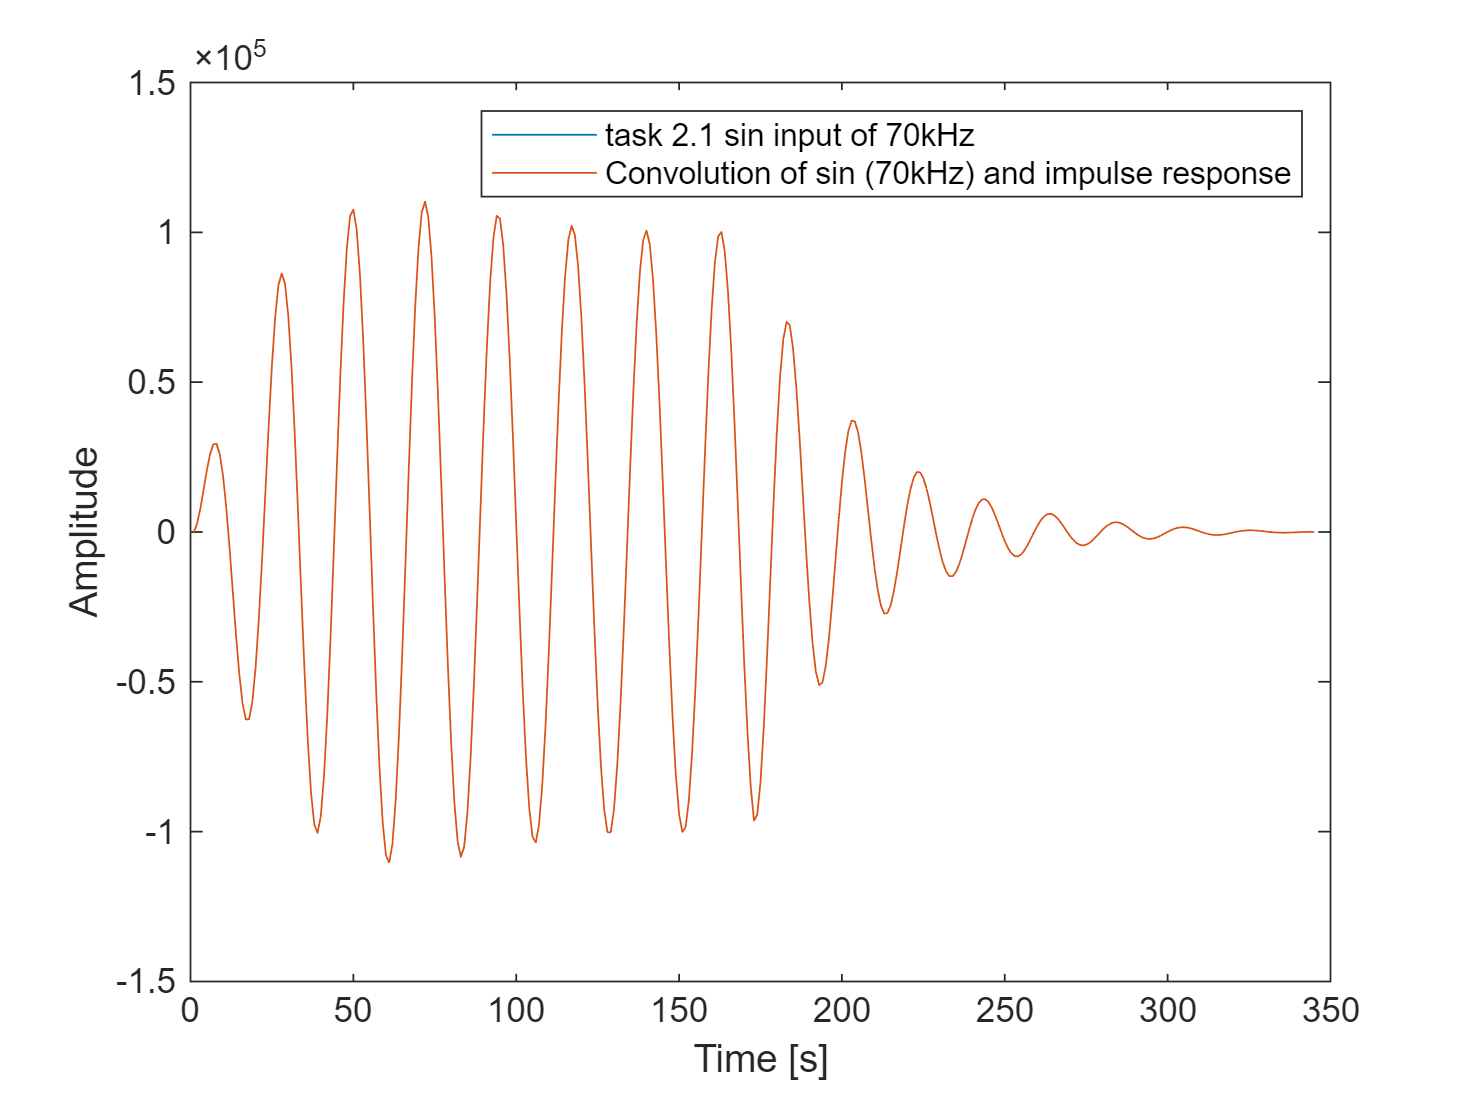

sin_wave=sin(2*pi*7000*tOut);
w = conv(y,sin_wave);
figure
plot(t,y4);hold on;
plot(w);hold off
legend('task 2.1 sin input of 70kHz','Convolution of sin (70kHz) and impulse response')
xlabel('Time [s]')
ylabel('Amplitude')

As seen on the plot, the two signals are the same. It makes sense because the impulse response convolved with some input is the same and measuring the systems response to the input.

function ownBode(x1,y1,fs)

N=length(x1);
X=fft(x1);
Y=fft(y1);
H=Y./X;
H_mag=abs(H);
df=fs/N;
f=(0:df:fs-1);
figure
title('Bode diagram')
subplot(211)
semilogx(f(1:floor(N/2))*2*pi,20*log10(H_mag(1:floor(N/2))))
title('Bode diagram')

xlim([10e3,10e6]);
ylabel('Magnitude [dB]')
subplot(212)
H_phase=angle(H);
semilogx(f(1:floor(N/2))*2*pi,rad2deg(H_phase(1:floor(N/2))))
xlim([10e3,10e6]);

ylabel('Phase [deg]')
xlabel('Frequency (rad/s)')
end